# Data-Driven Control Homework - SIDRA 2024 - Giorgio Ridolfi - Assignment 2

clc
close all
clear all

rng(1);

% addpath("/home/gio/Scrivania/lezioni/lezione_assignment_datadriven_sidra_2024/datadriven_sidra2024/cvx/")
% cvx_setup

    

% Order of the system variables ( state , input , disturbance )
nx = 4 ;
nu =1;

% Length of the input sequence
T = 10 ;


% Generating the input sequence u on [0,T-1] taking values in the interval
% [-1,1]^m in the form of an m x T matrix [u(0) u(1) .... u(T-1)]
magnitude=1;
aux=zeros(nu,T);
aux(:)=magnitude;
u(1:nu,1:T)=(2*magnitude).*rand(nu,T)-aux;

% Arranging the samples in the Hankel matrix U0 on [0,T-1]
for j=1:T-nu+1
    for i=1:nu
        
    U0((i-1)*nu+1:(i-1)*nu+nu,j)=u(1:nu, j+i-1);
    end
end
if rank(U0) == nu*nu
disp("input sequence is PE");
end

input sequence is PE



A = [ 0.5780 0.8492 0.4220 0.1508 ; 
      -0.6985 0.5780 0.6985 0.4220 ; 
      0.4220 0.1508 0.5780 0.8492 ;
      0.6985 0.4220 -0.6985 0.5780 ] ; 

B = [ 0.4160 ; 
     0.8492 ; 
     0.0390 ; 
     0.1508 ];

x = zeros(4,T+1);
x0 = randn(4,1) ;
x(:,1) = x0;




% Simulate system
for t = 1 : T
    x(:, t+1) = A*x(: , t) + B*u(t); 
end

X0 = x(:,1:end-1);
X1 = x(:,2:end);


figure
subplot(2 , 2 , [1 2 ])

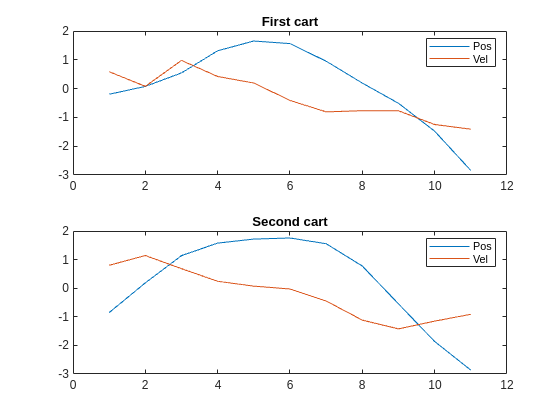


xlabel("Step")
plot(x(1,:))
hold on 
plot(x(2,:))
legend("Pos","Vel")
title("First cart")


subplot(2 , 2 , [3 4 ])

xlabel("Step")
plot(x(3,:))
hold on 
plot(x(4,:))
legend("Pos","Vel")
title("Second cart")


% LQR Parameters
Qx = eye(4);
R = 1 ; 

% Generate stabilizing controller
cvx_begin sdp
variable Y(T,nx)
variable L(nu,nu) symmetric
variable P(nx,nx) symmetric
minimize ( trace(Qx*P) +trace(L) )
[L, sqrtm(R)*U0*Y; Y'*U0'*sqrtm(R)', P] >= 0
[P-eye(nx), X1*Y; Y'*X1', P] >= 0
P==X0*Y
cvx_end

 
Calling SDPT3 4.0: 67 variables, 51 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 51
 dim. of sdp    var  = 13,   num. of sdp  blk  =  2
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.5e+01|3.7e+01|6.7e+04| 1.040000e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.847|0.958|3.9e+00|1.6e+00|9.0e+02|-1.018387e+00 -3.401779e+01| 0:0:00| chol  1  1 
 2|0.830|0.933|6.6e-01|1.2e-01|6.5e+01|-9.958364e+00 -3.132508e+01| 0:0:00| chol  1  1 
 3|1.000|0.7

K = U0*Y*inv(P)

K =    -0.2355   -1.1094   -0.2942   -0.4621


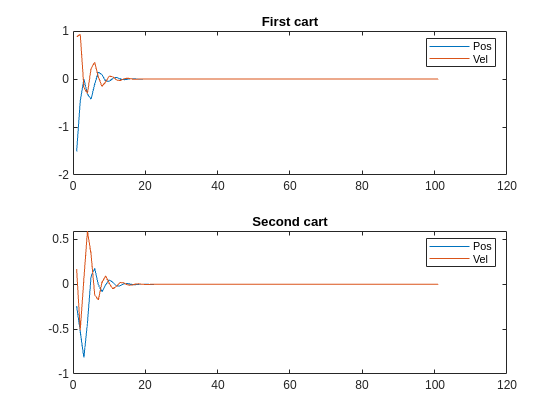

% Obtain the controller


T= 10*T ;
x = zeros(4,T+1);
x0 = randn(4,1) ;
x(:,1) = x0;

% Simulate closed loop system for longer
for t = 1 : T
    x(:, t+1) = (A + B*K)*x(: , t) ; 
end

X0 = x(:,1:end-1);
X1 = x(:,2:end);


figure
subplot(2 , 2 , [1 2 ])

xlabel("Step")
plot(x(1,:))
hold on 
plot(x(2,:))
legend("Pos","Vel")
title("First cart")


subplot(2 , 2 , [3 4 ])

xlabel("Step")
plot(x(3,:))
hold on 
plot(x(4,:))
legend("Pos","Vel")
title("Second cart")